San Diego sea level, annual averages, units = mm

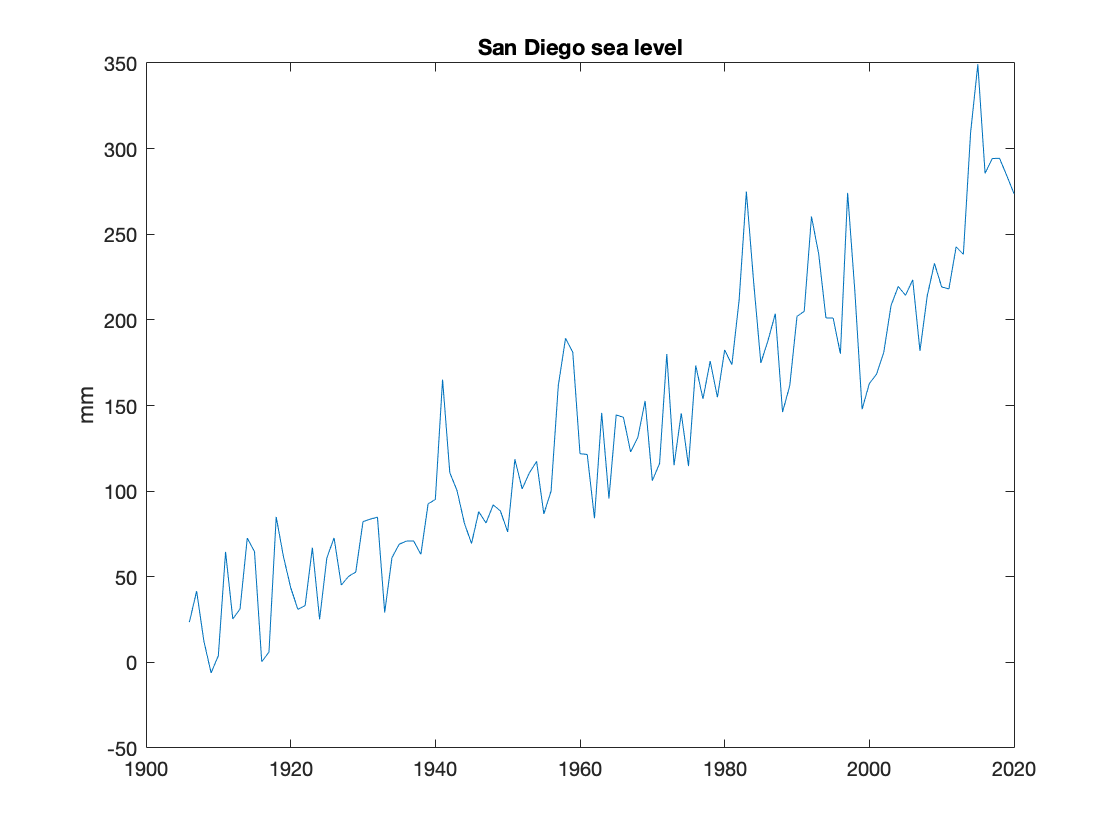

load SanDiego_ann_sealevel.mat
figure (1)
clf
plot(yr,h)
ylabel('mm')
title('San Diego sea level')

Compute linear trend using regress

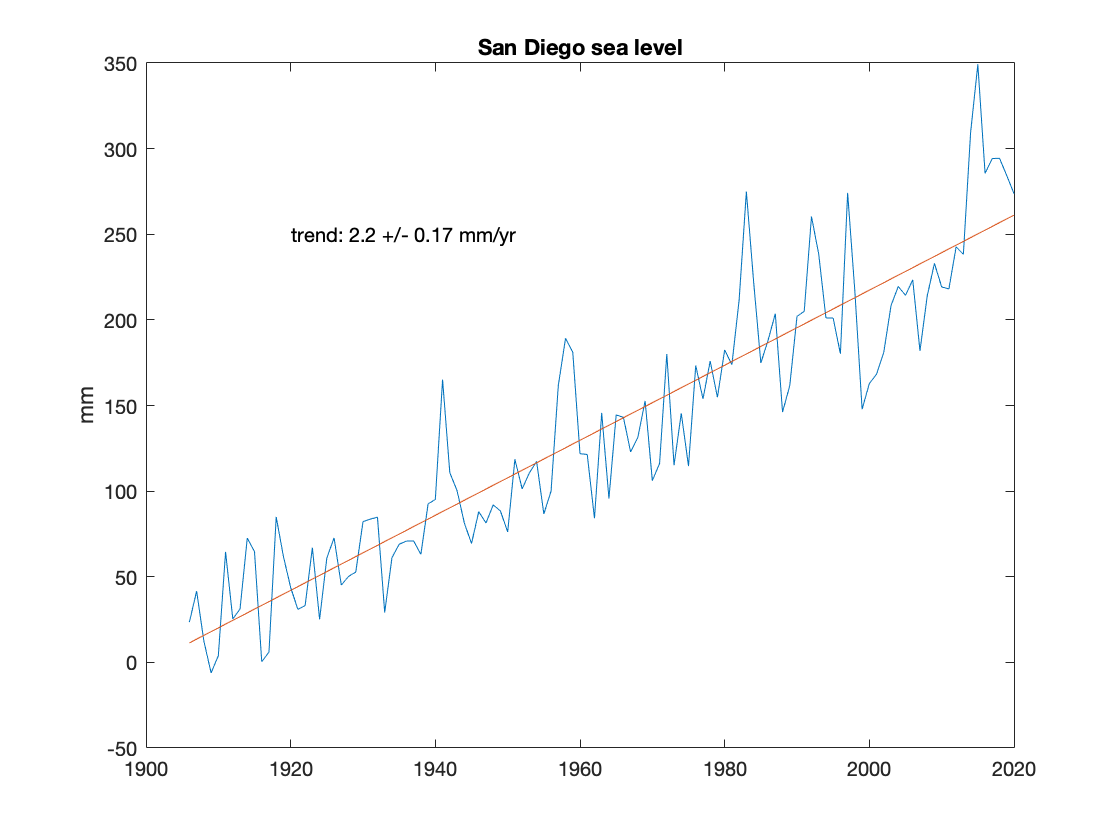

x = [yr-nanmean(yr) ones(length(yr),1)];
[b,bint] = regress(h,x);
figure (2)
clf
plot(yr,h,yr,x*b)
ylabel('mm')
title('San Diego sea level')
ci = (bint(1,2)-bint(1,1))/2;
a = ['trend: ',num2str(b(1),2),' +/- ',num2str(ci,2),' mm/yr']; %num2str 2 significant digits
text(1920,250,a)

Compute quadratic trend using regress

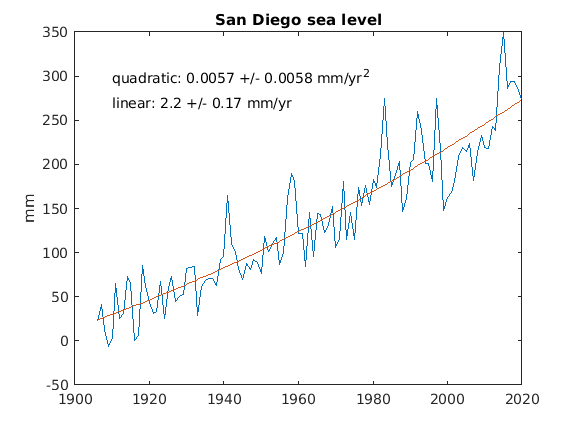

t0 = yr-nanmean(yr);
x2 = [t0.^2 t0 ones(length(yr),1)];
[b2,b2int] = regress(h,x2);
figure (3)
clf
plot(yr,h,yr,x2*b2)
ylabel('mm')
title('San Diego sea level')
ci1 = (b2int(1,2)-b2int(1,1))/2;
ci2 = (b2int(2,2)-b2int(2,1))/2;
a1 = ['quadratic: ',num2str(b2(1),2),' +/- ',num2str(ci1,2),' mm/yr^2'];
a2 = ['linear: ',num2str(b2(2),2),' +/- ',num2str(ci2,2),' mm/yr'];
text(1910,300,a1)
text(1910,270,a2)

Extrapolate to 2100

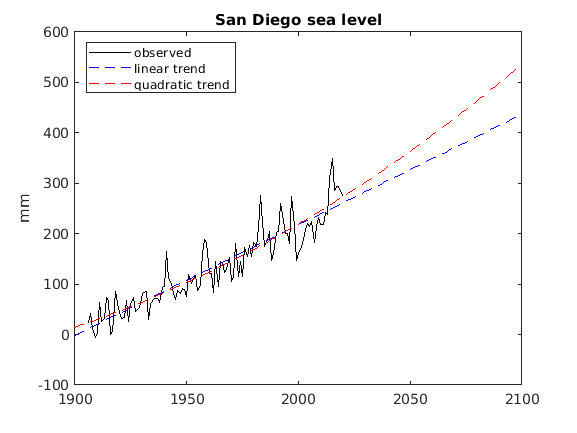

tf = (1900:2100)';
t0 = tf-mean(yr);
xf = [t0 ones(length(tf),1)];
figure (4)
clf
plot(yr,h,'k')
hold on
plot(tf,xf*b,'b--')
ylabel('mm')
title('San Diego sea level')
xf2 = [t0.^2 t0 ones(length(tf),1)];
plot(tf,xf2*b2,'r--')
legend('observed','linear trend','quadratic trend'),
legend('location','northwest')